# Reusable Superclasses for Hand-Code Apps

## Why use these superclasses?

After you've learned the basics of developing apps in MATLAB, you may find your work can become repetitive and tedious. Writing your apps programmatically using hand code provides much more control and flexibility for development, enabling you to realize significant gains in productivity and effectiveness. Moreover, there are notable commonalities between apps' requirements that are very repetitive. Using an object-oriented framework that enables you to inherit and reuse common capabilities is imperative to maximize your ability to provide a high-quality user experience with minimum development effort. 

## What superclass should I use?

There are three choices currently provided in Widgets Toolbox. The choice depends on whether your app should have one or more user sessions (like a document) that can be saved and loaded from the app. The selections for superclass are:

- [`wt.apps.BaseApp`](matlab:open('..\+wt\+apps\BaseApp.m'))`:` This is the most basic superclass. Choose this if your app does not need to save a session to disk. 

- [`wt.apps.BaseSingleSessionApp`](matlab:open('..\+wt\+apps\BaseSingleSessionApp.m')): Choose this if your app must be able to save and load a session (document) to disk.

- [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')): Choose this if your app would enable the user to have multiple sessions loaded into the app simultaneously. (This is the most complex superclass, and it is the least common scenario.)

In order to use these superclasses, you must build your top-level application as a hand-coded MATLAB class. The superclasses are **not** compatible with App Designer .mlapp files, because you are unable to modify the inheritance of the app class in .mlapp format.

## Example hand-code apps using the superclasses

To better understand the usage of these classes, please review these examples and their source code:

#### Working with Hierarchical Data: Zoo Hierarchy App

The Zoo Hierarchy App Example utilizes the [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')) superclass, enabling the user to visualize and compare data among one or more saved session files. 

wtExamplesFolder
edit AdvancedAppZooHierarchyExample.mlx

This document describes an advanced app that enables interaction with hierarchical data. The app is implemented in hand-code and shows the use of object-oriented programming and model-view-controller.

## Class Reference

The application superclasses useful for hand-coded apps are explained in the sections below. These classes reside in the within the `wt.apps` and `wt.model` packages. The relationship between these superclasses is shown in Figure 1:

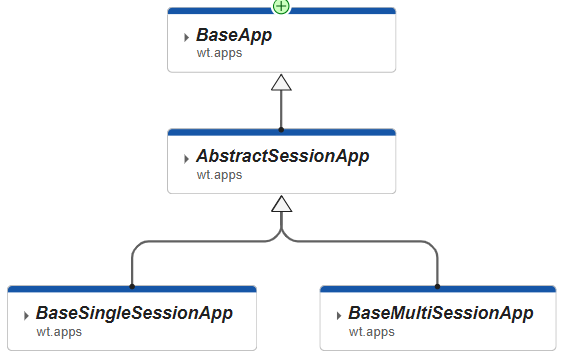

*Figure 1. UML class diagram showing the inheritance relationship of the app superclasses*

### BaseApp

The [`wt.apps.BaseApp`](matlab:open('..\+wt\+apps\BaseApp.m')) class provides common, reusable functionality for apps that are written using hand code. The primary features include:

- Encapsulating and preparing the figure window.

- Launching the app's figure into the last used position, while ensuring it is visible on screen.

- Storing user preferences including recent folder for file operations plus custom app-specific preferences. (Please see [App Preferences](matlab:open('./AppPreferences.html')) for implementing custom preferences for your app.)

- Organizing app code into `setup` and `update` methods, similar to [ComponentContainer](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) and [ChartContainer](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html) classes.

- Providing helper methods for commonly used dialogs.

 The programming interface implemented in `BaseApp` is shown in the tables below:

#### Properties

#### Methods

## AbstractSessionApp

The [`wt.apps.AbstractSessionApp`](matlab:open('..\+wt\+apps\AbstractSessionApp.m')) class is a superclass to both [`wt.apps.BaseSingleSessionApp`](matlab:open('..\+wt\+apps\BaseSingleSessionApp.m')) and [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')) that implements common functionalities for saving, loading, and monitoring user sessions. You can not directly inherit `AbstractSessionApp` from your app's concrete class, but the functionality below will be included with either `BaseSingleSessionApp` or `BaseMultiSessionApp`. The additional features implemented in `AbstractSessionApp` include:

- Management of the user's session state (or "document") being used in the app.

- Save and load of these user sessions to a file.

- Listening to session changes to track "dirty" state and notify app of changes.

- Prompts to save changes before closing as necessary.

Using this superclass includes the interface from `BaseApp``. `The programming interface implemented in `AbstractSessionApp` is shown in the tables below:

#### Properties

#### Methods

## BaseSingleSessionApp

The [`wt.apps.BaseSingleSessionApp`](matlab:open('..\+wt\+apps\BaseSingleSessionApp.m')) class provides common, reusable functionality for apps that are written using hand code and have a single session. The primary features added by `BaseSingleSessionApp` include:

- File management of a single session in the app

- Provides user promptss to handle unsaved changes

When using this superclass, you must also create a session class that inherits from [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')). For more information on this, please see [REFERENCE FOR BASESESSION / BASEMODEL].

This superclass includes the previously described interfaces from `BaseApp` and `AbstractSessionApp``.` The programming interface implemented in `BaseSingleSessionApp` is shown in the tables below:

#### Properties

#### Methods

## BaseMultiSessionApp

The [`wt.apps.BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')) class provides common, reusable functionality for apps that are written using hand code and have a single session. The primary features added by `BaseMultiSessionApp` include:

- File management of a multiple sessions in the app

- Provides user prompts to handle unsaved changes

When using this superclass, you must also create a session class that inherits from [`wt.model.BaseSession`](matlab:open('..\+wt\+model\BaseSession.m')). 

This superclass includes the previously described interfaces from `wt.apps.BaseApp` and `wt.apps.AbstractSessionApp``.` The programming interface implemented in `BaseMultiSessionApp` is shown in the tables below:

#### Properties

#### Methods

### Examples

#### Working with Hierarchical Data: Zoo Hierarchy App

This document describes an advanced app that enables interaction with hierarchical data. The app is implemented in hand-code and shows the use of object-oriented programming and model-view-controller.

wtExamplesFolder
edit AdvancedAppZooHierarchyExample.mlx

## Related Content

- [Widgets Toolbox - Documentation Home](matlab:open('./MainPage.html'))

- [Advanced App Development with Widgets Toolbox](matlab:open('./AdvancedAppDevelopment.html'))

- [App Preferences](matlab:open('./AppPreferences.html'))

*Copyright 2020-2025 The MathWorks, Inc.*